**Question 6**

The parameters $d_{21}$ and $d_{22}$ are changed to $47\ldotp 2470\times {10}^{-4\;} \textrm{cm}$ 

% electrical constants and derived quantities for typical 
% mammalian dendrite

% Dimensions of compartments

d1 = 75e-4; 			% cm
%d21 = 30e-4; 			% cm
%d22 = 15e-4; 			% cm
d21 = 47.2470e-4;       % E9 cm
d22 = d21;               % E9 cm

l1 = 1.5;			% dimensionless
l21 = 3.0;			% dimensionless
l22 = 3.0;			% dimensionless

% Electrical properties of compartments

Rm = 6e3;			% Ohms cm^2
Rc = 90;			% Ohms cm
Rs = 1e6;			% Ohms

c1 = 2*(Rc*Rm)^(1/2)/pi;

rl1 = c1*d1^(-3/2);		% Ohms
rl21 = c1*d21^(-3/2);		% Ohms
rl22 = c1*d22^(-3/2);		% Ohms


% Applied current

iapp = 1e-9; 	% Amps

% Coefficient matrices

A = [1 -1 0 0 0 0;
     0 0 exp(-l21) exp(l21) 0 0;
     0 0 0 0 exp(-l22) exp(l22);
     exp(-l1) exp(l1) -exp(-l1) -exp(l1) 0 0;
     0 0 exp(-l1) exp(l1) -exp(-l1) -exp(l1);
     -exp(-l1) exp(l1) rl1*exp(-l1)/rl21 -rl1*exp(l1)/rl21 rl1*exp(-l1)/rl22 -rl1*exp(l1)/rl22];

b = [rl1*iapp 0 0 0 0 0]';


x=A\b;
display(x);

x = 1.0e-03 *

    0.7185
   -0.0018
    0.7185
   -0.0018
    0.7185
   -0.0018


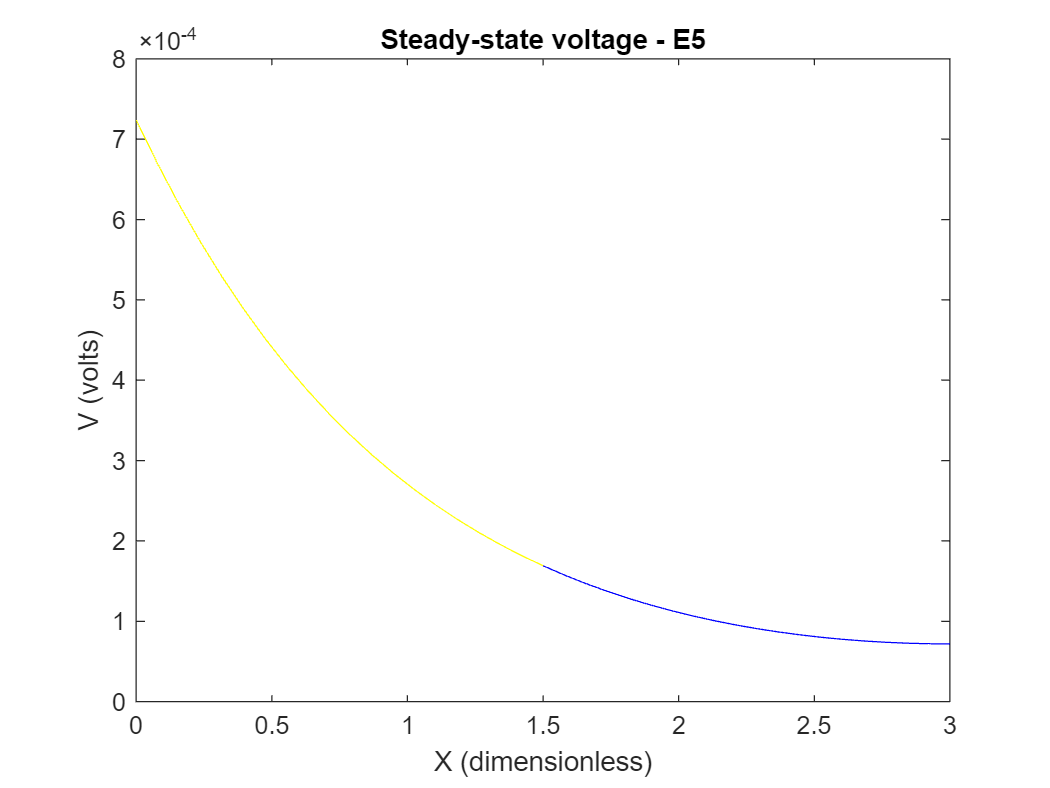

 % Update boundary conditions
 A(2,:) = [0 0 -exp(-l21) exp(l21) 0 0];
 A(3,:) = [0 0 0 0 -exp(-l22) exp(l22)];

 x = A\b;

 y1 = linspace(0,l1,20);
 y21 = linspace(l1,l21,20);
 y22 = linspace(l1,l22,20);

 v1 = x(1)*exp(-y1) + x(2)*exp(y1);
 v21 = x(3)*exp(-y21) + x(4)*exp(y21);
 v22 = x(5)*exp(-y22) + x(6)*exp(y22);

 plot(y1, v1, 'y-', y21, v21, 'r-', y22, v22, 'b-');
 xlabel('X (dimensionless)');
 ylabel('V (volts)');
 title('Steady-state voltage - E5');

**Part d)**

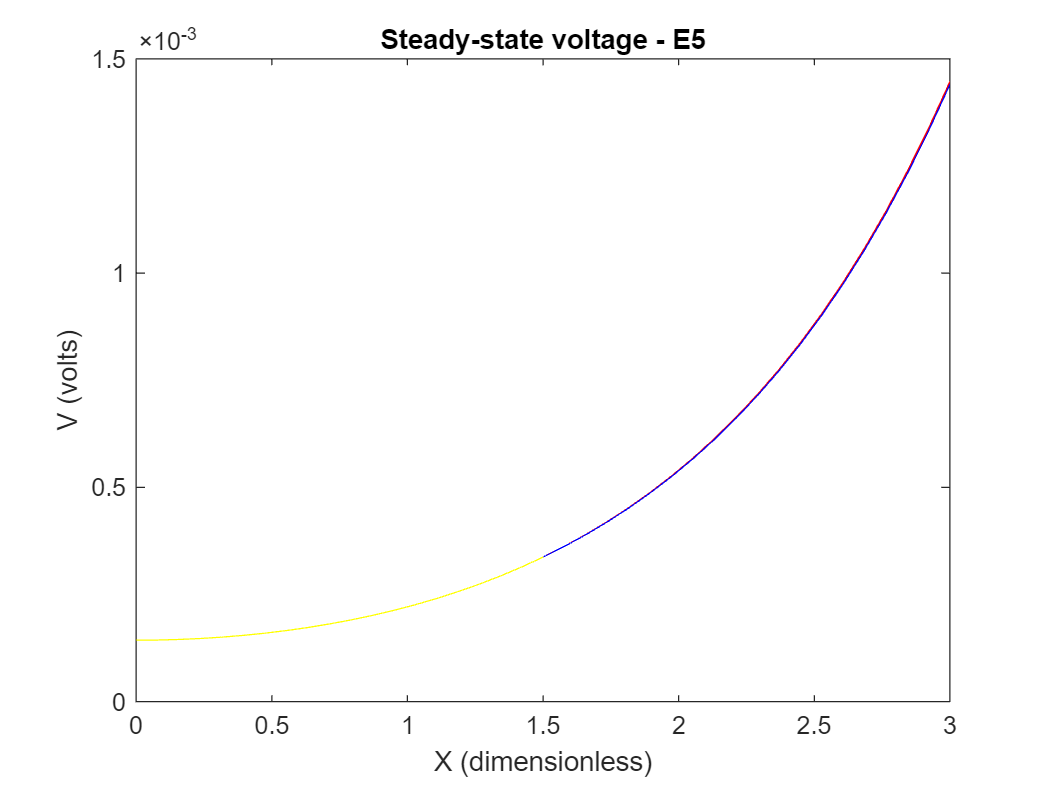

% Update the boundary conditions
A(3,:) = [0 0 0 0 exp(-l22) exp(l22)];
b(1) = 0; b(2) = rl21*iapp;
b(3) = rl22*iapp;

x = A\b;

y1 = linspace(0,l1,20);
y21 = linspace(l1,l21,20);
y22 = linspace(l1,l22,20);

v1 = x(1)*exp(-y1) + x(2)*exp(y1);
v21 = x(3)*exp(-y21) + x(4)*exp(y21);
v22 = x(5)*exp(-y22) + x(6)*exp(y22);

plot(y1, v1, 'y-', y21, v21, 'r-', y22, v22, 'b-');
xlabel('X (dimensionless)');
ylabel('V (volts)');
title('Steady-state voltage - E5');

** What do you notice?**

The graphs have become smoother at the branching point, with no sudden changes. The voltage profiles of both daughter branches are approximately the same in both cases. This is because the two daughter branches have equal diameters, allowing them to carry equal amounts of current.